%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% alinea (e)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
q = @(x) -1 + 0.5.*sin(20.*x);
r = @(x) 1 + 30.*(1-x).^2;
l = 0.5;

Fz = @(t, x, y) [y; -q(t).*x + r(t)];
Fw = @(t, x, y) [y; -q(t).*x];

h_vals = [0.2, 0.1, 0.05, 0.025];
max_vals = zeros(1, 4);

figure; hold on;
for idx = 1:4
    h = h_vals(idx);
    [z, ~] = rungekutta(h, 0, 0, Fz, 1);
    [w, ~] = rungekutta(h, 0, 1, Fw, 1);
    s = (l - z(end)) ./ w(end);
    y = z + s.*w;
    x = 0:h:1;
    max_vals(idx) = max(abs(y));
    plot(x, y, 'DisplayName', sprintf('h = %.3f', h));
end

abs(max_vals(3) - max_vals(4))

ans =      1.156719844359611e-04


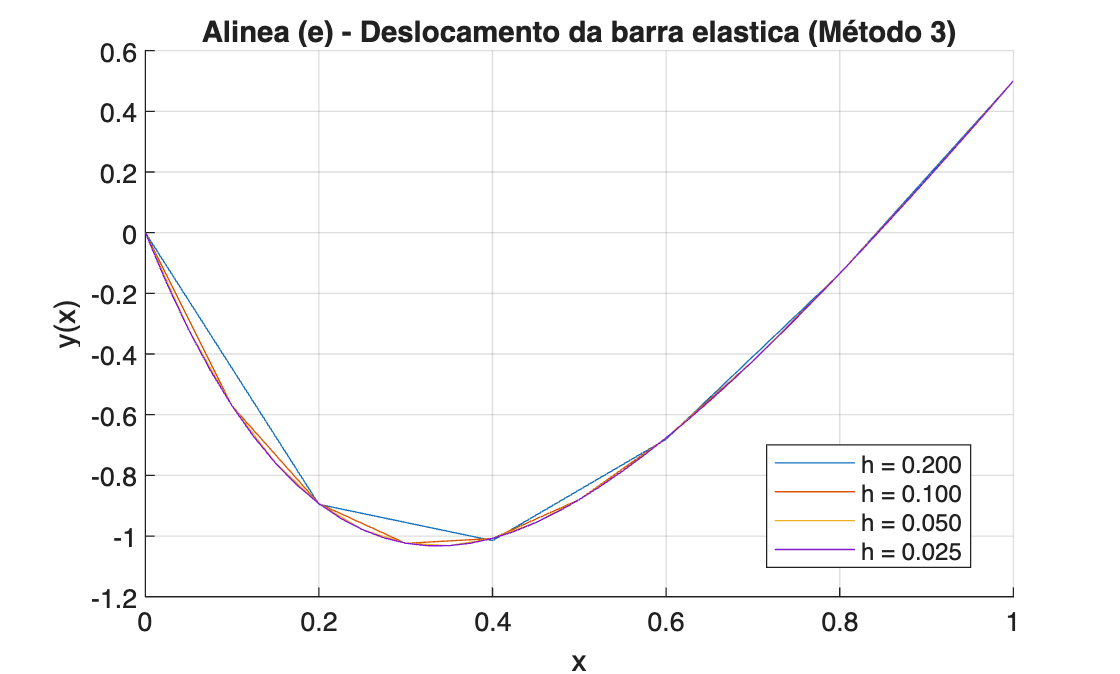

xlabel('x'); ylabel('y(x)');
title('Alinea (e) - Deslocamento da barra elastica (Método 3)');
legend('Location', 'best');
grid on; hold off;


% resultado final com h=0.025
h = 0.025;
[z, ~] = rungekutta(h, 0, 0, Fz, 1);
[w, ~] = rungekutta(h, 0, 1, Fw, 1);
y = z + (l - z(end))./w(end).*w;
x = 0:h:1;
[ymax, idx_max] = max(abs(y));
fprintf('Deslocamento maximo: %f em x = %.4f\n', ymax, x(idx_max));

Deslocamento maximo: 1.031912 em x = 0.3250
